# Lineáris Regresszió

ZH a kilencedig témáig lesz csak,- Nem paraméteres próbák, mindenre van gyakorló feladat, az elegendő a ZH teljesítéséhez.

Importáljuk be a 'weight-height.csv' fájlt, amely 10,000 megfigyelést tartalmaz 5,000 férfi és 5,000 nő esetén a súlyuk ( **weight** ~pounds) és magasságuk ( **height** ~inches) szerint. Váltsuk át a mértékeket *kg-*ba és *cm-*be.

data = readtable("weight-height.csv");
data.Height = data.Height*2.54;
data.Weight = data.Weight*0.45;


Vizsgáljuk meg grafikusan a kapcsolatot a magasság és súly között. Számoljuk ki a korrelációs együtthatót.

Erős kolleráció, pozitív. Lineáris.

*Spearman-Pearson korreláció különbségét nézd meg*

Regressziós egyenes:

Yi = B1X1^i +  BnXn^i + Bo + Ei, ahol

Ei - hibatag

Ei~(W(0,gamma^2)


$$\text{Súly = $\beta_0$ + $\beta_1$\cdot Magasság}$$


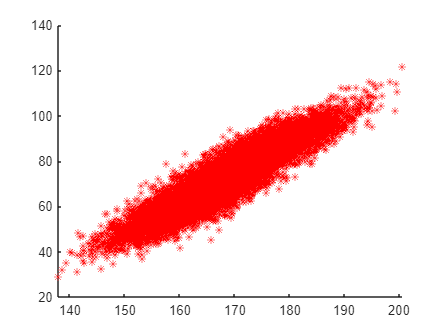

scatter(h,w,"r*")

corr(h,w)

ans = 0.9248

A következő modell paramtéereit szeretnénk becsülni:

Ábrázoljuk a pontokat a regressziós egyenessel és a 95%-os konfidencia határokkal.

linmod = fitlm(h,w,'linear')

linmod = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat     pValue
                   ________    _________    _______    ______

    (Intercept)    -157.83       0.95017    -166.11      0   
    x1              1.3672     0.0056271     242.97      0   


Number of observations: 10000, Error degrees of freedom: 9998
Root Mean Squared Error: 5.5
R-squared: 0.855,  Adjusted R-Squared: 0.855
F-statistic vs. constant model: 5.9e+04, p-value = 0

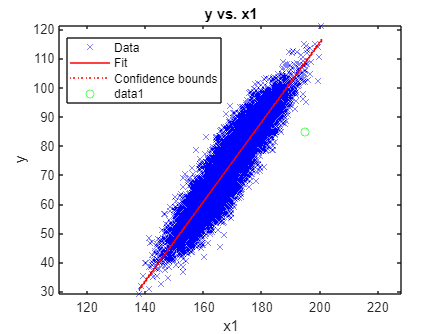


plot(linmod)
hold on
plot(195,85,"go")
axis equal
hold off

Használjon 95%-os kofidencia intervallumot a saját magasságára (cm).

[y ci] = predict(linmod, 195,'Prediction', 'observation','Alpha',0.01)

y = 108.7793

ci =    94.6064  122.9521


Ábrázolja a 99%-os kofidencia intervallumot a megfigyelésekre!

scatter(h,w)
x = linspace(min(h),max(h));
[y ci] = predict(linmod, x','Prediction', 'observation', ...
    'Alpha',0.01);
hold on
plot(x,y,'r',x,ci(:,1),'g',x,ci(:,2),'g')
hold off

Vegyen 100 véletleszerű megfigyelést a teljes adathalmazból. Hajtsa végre rajta az előzőeket.

rng(1); ind = randi(10000,100,1);
subdata = data(ind,:);
sh = subdata.Height*2.54;
sw = subdata.Weight*.45;
sublm = fitlm(sh,sw,'linear')

sublm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -66.463      4.3533    -15.268    1.1801e-27
    x1             0.23155     0.01008     22.971    3.0974e-41


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 2.64
R-squared: 0.843,  Adjusted R-Squared: 0.842
F-statistic vs. constant model: 528, p-value = 3.1e-41

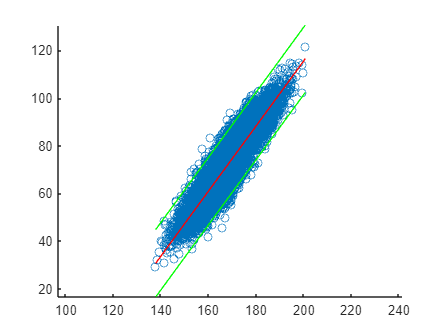

axis equal

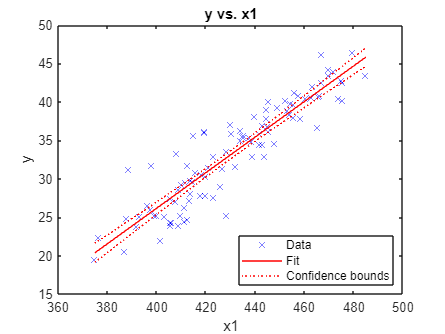

plot(sublm)

## Feladat

- Hasonlítsuk össze a nemek szerint a korrelációkat. 

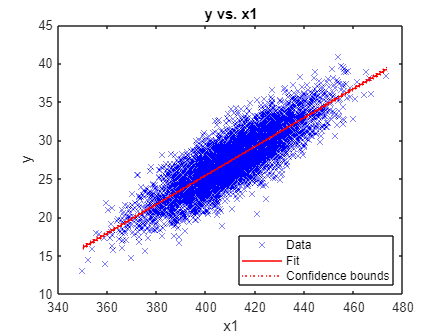

noind = data.Gender==("Female");


no = data(noind,:);

nh = no.Height*2.54;
nw = no.Weight*0.45;
plot(fitlm(nh,nw,'linear'))

corr(nh,nw)

ans = 0.8496

ferfi = data(ferfiind,:);
ferfiind = data.Gender=="Male";
fh=ferfi.Height*2.54;
fw=ferfi.Weight*0.45;
sublm=fitlm(fh,fw,'linear')

sublm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat     pValue
                   ________    _________    _______    ______

    (Intercept)    -45.461        0.6907    -65.819      0   
    x1             0.18713     0.0015496     120.75      0   


Number of observations: 5000, Error degrees of freedom: 4998
Root Mean Squared Error: 2.02
R-squared: 0.745,  Adjusted R-Squared: 0.745
F-statistic vs. constant model: 1.46e+04, p-value = 0

plot(sublm)
corr(fh,fw)

ans = 0.8630

corr(195,85)

ans = NaN

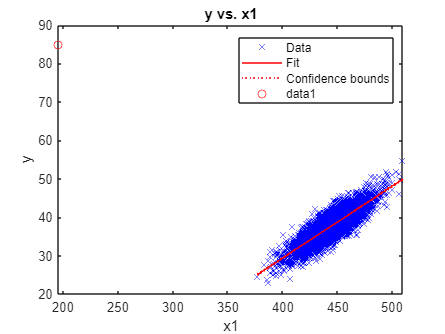

hold on
plot(195,85,"ro")
hold off


[y ci ] = predict(sublm,195,'Prediction','Observation')

y = -8.9715

ci =   -13.0121   -4.9309


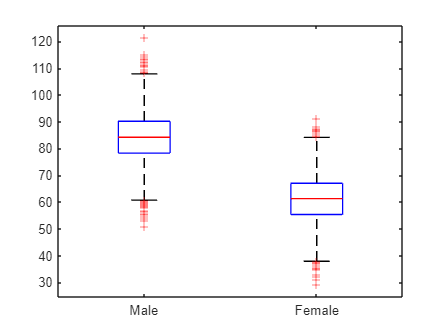

boxplot(w,data.Gender)

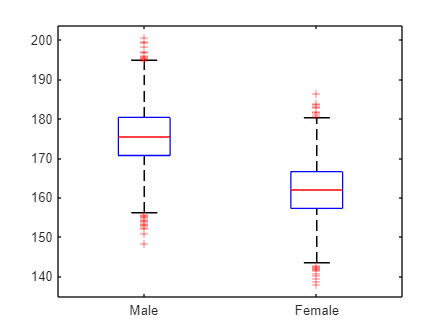


boxplot(h,data.Gender)

- Használja csak a saját neméhez tartozó modellt. Hasonlítsa össze a modell paramétereket.


data.bmi=w./((h/100).^2)

data = 10000×4 table
     Gender     Height    Weight     bmi  
    ________    ______    ______    ______

    {'Male'}    187.57    108.85    30.939
    {'Male'}    174.71     73.04     23.93
    {'Male'}    188.24    95.733    27.017
    {'Male'}     182.2    99.019    29.829
    {'Male'}     177.5    92.857    29.473
    {'Male'}    170.82    68.495    23.473
    {'Male'}    174.71    82.768    27.115
    {'Male'}    173.61    75.587     25.08
    {'Male'}    170.23    79.168     27.32
    {'Male'}    161.18     70.38    27.091
    {'Male'}    180.84    83.972    25.678
    {'Male'}    181.97    96.184    29.048
    {'Male'}    164.51    75.207     27.79
    {'Male'}    175.98    85.251    27.528
    {'Male'}    175.88    83.895    27.121
    {'Male'}    171.82    77.484    26.246


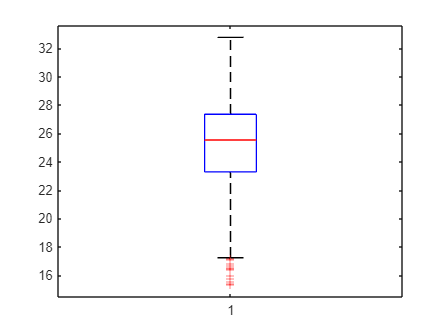

boxplot(data.bmi)


data

data = 10000×4 table
     Gender     Height    Weight     bmi  
    ________    ______    ______    ______

    {'Male'}    187.57    108.85    30.939
    {'Male'}    174.71     73.04     23.93
    {'Male'}    188.24    95.733    27.017
    {'Male'}     182.2    99.019    29.829
    {'Male'}     177.5    92.857    29.473
    {'Male'}    170.82    68.495    23.473
    {'Male'}    174.71    82.768    27.115
    {'Male'}    173.61    75.587     25.08
    {'Male'}    170.23    79.168     27.32
    {'Male'}    161.18     70.38    27.091
    {'Male'}    180.84    83.972    25.678
    {'Male'}    181.97    96.184    29.048
    {'Male'}    164.51    75.207     27.79
    {'Male'}    175.98    85.251    27.528
    {'Male'}    175.88    83.895    27.121
    {'Male'}    171.82    77.484    26.246


normal= data(data.bmi<25 & data.bmi>18.5,:)

normal = 4328×4 table
     Gender     Height    Weight     bmi  
    ________    ______    ______    ______

    {'Male'}    174.71     73.04     23.93
    {'Male'}    170.82    68.495    23.473
    {'Male'}    168.02    67.128    23.779
    {'Male'}    172.45    72.903    24.515
    {'Male'}    173.98    69.454    22.945
    {'Male'}     187.5    87.881    24.997
    {'Male'}     181.4    80.939    24.596
    {'Male'}    171.69    73.399    24.899
    {'Male'}     177.3    77.869    24.772
    {'Male'}    168.34    69.478    24.518
    {'Male'}    171.59    71.356    24.234
    {'Male'}     174.9    76.301    24.942
    {'Male'}    165.99    66.033    23.966
    {'Male'}    177.64    76.579    24.267
    {'Male'}    171.96    71.679     24.24
    {'Male'}    170.26     70.42    24.292


sumlm=fitlm(normal.Height,normal.Weight,"linear")

sumlm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat     pValue
                   ________    _________    _______    ______

    (Intercept)    -98.805        1.1886    -83.125      0   
    x1             0.98123     0.0073376     133.73      0   


Number of observations: 4328, Error degrees of freedom: 4326
Root Mean Squared Error: 3.43
R-squared: 0.805,  Adjusted R-Squared: 0.805
F-statistic vs. constant model: 1.79e+04, p-value = 0

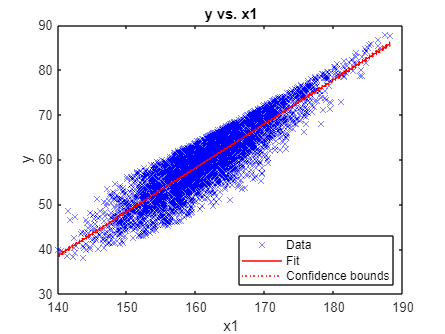


plot(sumlm)

corr(normal.Height,normal.Weight)

ans = 0.8973


[v ci ] = predict(sumlm,195,'Prediction','Observation','Alpha',0.01)

v = 92.5351

ci =    83.6747  101.3955
